# Spline DEMO

Demonstrație cu spline cubice

Alegem funcția $f(x)=x(x-1)(x-2)(x-3)(x-4)$ și nodurile $x_k=k$, $k=0,\dots,4$

f = @(x) x.*(x-1).*(x-2).*(x-3).*(x-4);
d=[24,24];
t=linspace(0,4,200)';
x=0:4; y=f(x);

## Spline complete

c1 = CubicSplinec(x,y,0,d);
s1 = evalsplinec(x,c1,t);

## spline cu derivate secunde

d2=[-100,100];
c2 = CubicSplinec(x,y,1,d2);
s2=evalsplinec(x,c2,t);

## spline naturale

c3 = CubicSplinec(x,y,2);
s3 = evalsplinec(x,c3,t);

## spline deBoor

c4 = CubicSplinec(x,y,3);
s4 = evalsplinec(x,c4,t);

## reprezentare grafica

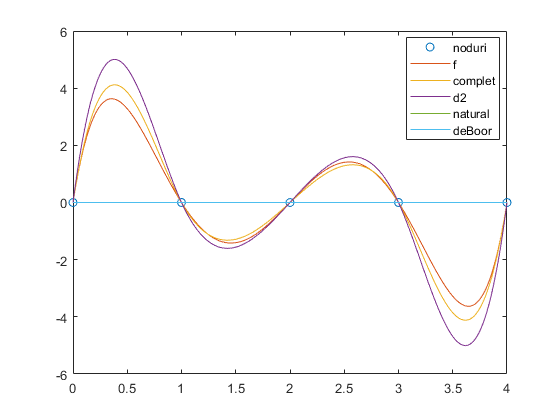

yg=f(t);
plot(x,y,'o',t,[yg,s1,s2,s3,s4])
legend('noduri','f','complet','d2','natural','deBoor','Location','best')